Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear

% helper vector com cores mais faceis aos olhos
colors = [[0, 0.4470, 0.7410]; ...
    [0.8500, 0.3250, 0.0980]; ...
    [0.9290, 0.6940, 0.1250]; ...
    [0.4940, 0.1840, 0.5560]; ...
    [0.4660, 0.6740, 0.1880]; ...
    [0.3010, 0.7450, 0.9330]; ...
    [0.6350, 0.0780, 0.1840]];

strF="y+exp(3*t)";
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 1;
b = 1.5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 5;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 2;

%Variables for ploting
h = (b-a)/n;
t = a:h:b;

yValue(:,1) = t.';
methods(1) = "t";

% Alinha automaticamente os graficos consoante o numero
% de metodos na figura
tiledlayout('flow');

if(false)
    [~, y]=NEuler(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Euler", y, t, colors(length(methods), :));
    methods(end+1) = "Euler";
end
if(false)
    [~, y]=NEulerMelhorado(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Euler Melhorado", y, t, colors(length(methods), :));
    methods(end+1) = "Euler M";
end
if(false)
    [~, y]=RK2(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("RK2", y, t, colors(length(methods), :));
    methods(end+1) = "RK2";
end
if(false)
    [~, y]=RK4(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("RK4", y, t, colors(length(methods), :));
    methods(end+1) = "RK4";
end
if(true)
    [~, y]=AdamBashforth(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Adams-Bashforth", y, t, colors(length(methods), :));
    methods(end+1) = "Adams-Bashforth";
end
if(true)
    [~, y]=sExata(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Exata", y, t, colors(length(methods), :));
    methods(end+1) = "Exata";
end
if(false)
    [t, y]=ode45(f, [a b], y0);
    %nao pode ser usada na funcao mostraTodos
    %porque usa um t diferente das outras funcoes
    fprintf("\nAproximações obtidas de ode45:\n");
    mostraGrafico("ode45", y, t, colors(length(methods), :));
    fprintf('\nPontos de aproximação da ode45\n');
    % mostra em linha
    disp(y.');
    disp(t.');
    % mostra em coluna
    % disp(table(y));
    % disp(table(t));
    hold on
    plot(t, y, 'DisplayName', 'ode45', 'Color', colors(7,:));
    hold off
end

% mostra dados da table
data = array2table(yValue, 'VariableNames', methods);
disp(data);

     t     Adams-Bashforth    Exata 
    ___    _______________    ______

      1             2              2
    1.1        4.2086         4.6677
    1.2        7.8025         8.4757
    1.3        13.358         13.845
    1.4        21.668         21.345
    1.5        33.817         31.748



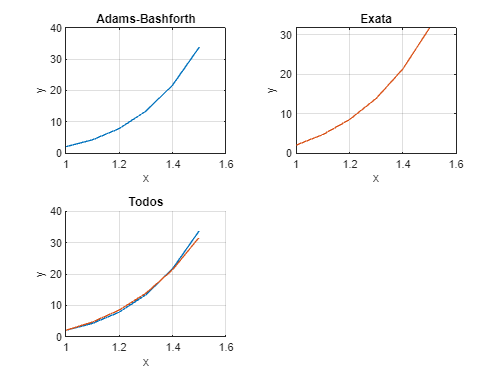


% mostrar os graficos todos juntos
mostraTodos(methods, yValue, colors);

clf reset;

function mostraGrafico(metodo, y, t, cor)
nexttile
plot (t, y, 'DisplayName', metodo, 'Color', cor);
title(metodo);
xlabel('x');
ylabel('y');
grid on
end

function mostraTodos(metodo, y, colors)
% Desenha todos num unico grafico
nexttile
title("Todos");
%t e um vetor que guarda o tamanho da matrix y
%com [linhas colunas]
t = size(y);
%O numero de metodos escolhidos e o numero de colunas na matriz y
hold on
for i = 2:t(2)
    plot (y(:,1).', y(:, i).', 'DisplayName', metodo(i), 'Color', colors((i-1),:));
    % legend('location', 'best');
end
hold off
grid on
xlabel('x');
ylabel('y');
end
